# Create Simulink Environment and Train Agent

Exemplo funciona no Matlab 2020a

This example shows how to convert the PI controller in the `watertank` Simulink® model. to a reinforcement learning deep deterministic policy gradient (DDPG) agent. For an example that trains a DDPG agent in MATLAB®, see [Train DDPG Agent to Balance Double Integrator Environment](docid:rl_ug#mw_0b71212e-521a-4a57-bde7-5dde0c1e0c90).

## Water Tank Model

The original model for this example is the water tank model. The goal is to control the level of the water in the tank. For more information about the water tank model, see [watertank Simulink Model](docid:slcontrol_gs#bsp4o3g).

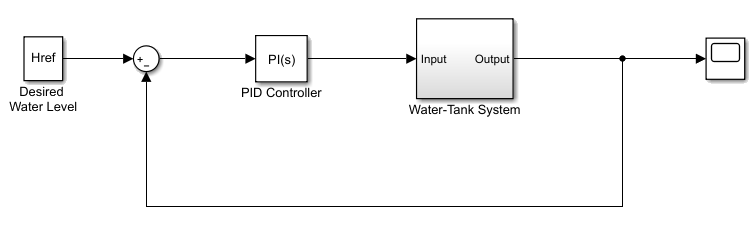

Modify the original model by making the following changes:

- Delete the PID Controller.

- Insert the RL Agent block.

- Connect the observation vector ${\left\lbrack \begin{array}{ccc}
\int e\;\textrm{dt} & e & h
\end{array}\right\rbrack }^{T\;}$, where $h$ is the height of the tank, $e=r-h$, and $r$ is the reference height.

- Set up the reward $\textrm{reward}=10\left(\left|e\right|<0\ldotp 1\right)-1\left(\left|e\right|\ge 0\ldotp 1\right)-100\left(h\le 0\left|\right|h\ge 20\right)$.

- Configure the termination signal such that the simulation stops if $h\le 0$ or $h\ge 20$.

The resulting model is `rlwatertank.slx`. For more information on this model and the changes, see [Create Simulink Environment for Reinforcement Learning](docid:rl_ug#mw_0e8060ca-2e7a-4d41-90d1-3bf4aeb76099).

open_system('meurlwatertank')

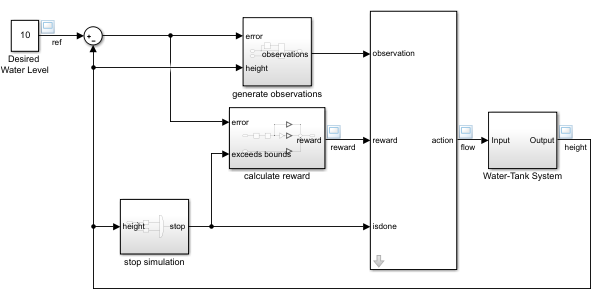

## Create Environment Interface

Creating an environment model includes defining the following:

- Action and observation signals that the agent uses to interact with the environment. For more information, see [rlNumericSpec](docid:rl_ref#mw_1a66fdf2-e758-4985-a541-61943fb15e79) and [rlFiniteSetSpec](docid:rl_ref#mw_68f70adf-d6a9-4cbe-846c-a7d0823c0774).

- Reward signal that the agent uses to measure its success. For more information, see [Define Reward Signals](docid:rl_ug#mw_1fe437df-5904-43dc-8b75-1e25bb9ae3ff).

Define the observation specification `obsInfo` and action specification `actInfo`.

obsInfo = rlNumericSpec([3 1],... %cria especificacao de espaço de observacao de estados continuo para ambiente RL (erro total, erro, e nivel)
    'LowerLimit',[-inf -inf 0  ]',...
    'UpperLimit',[ inf  inf inf]'); 

obsInfo.Name = 'observations';
obsInfo.Description = 'integrated error, error, and measured height';
numObservations = obsInfo.Dimension(1);

actInfo = rlNumericSpec([1 1]); %cria especificacao de espaço de acao continuo para ambiente RL (erro total, erro, e nivel)
actInfo.Name = 'flow';
numActions = actInfo.Dimension(1);

Build the environment interface object.

env = rlSimulinkEnv('meurlwatertank','meurlwatertank/RL Agent',...
    obsInfo,actInfo); %cria objeto de ambiente de RL usando o modelo simulink, o caminho do bloco agente, objeto de observacoes e objeto de acoes

Set a custom reset function that randomizes the reference values for the model.

env.ResetFcn = @(in)localResetFcn(in); % define uma funcao de reinicio para o ambiente, para novo episodio, a funcao esta la embaixo desse arquivo
                                       % "in" é um objeto que representa a
                                       % simulacao no simulink, é enviado
                                       % automaticamente para essa funcao

Specify the simulation time `Tf` and the agent sample time `Ts` in seconds.

Ts = 1.0; %tempo de amostragem do agente
Tf = 200; %tempo total de simulacao, portanto 200 passos no maximo

Fix the random generator seed for reproducibility.

rng(0)  % semente para o gerador de valores aleatorios se repetitivo

## Create DDPG Agent

Given observations and actions, a DDPG agent approximates the long-term reward using a critic value function representation. To create the critic, first create a deep neural network with two inputs, the observation and action, and one output. For more information on creating a deep neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

%criar a rede da representacao Value do agente

statePath = [
    imageInputLayer([numObservations 1 1],'Normalization','none','Name','State') % nao confundir com entrada de imagem, 
                                                                                 % é só um aproveitamento desse tipo de camada de entrada, o matlab 2020b tem uma camada melhor para isso 
                                                                                 % esta declarando normalizacao como nenhuma, pq o padrão dessa camada é normalizar os valores de entrada pela média, e não precisamos disso aqui
                                                                                 % da para criar a propria camada com o tutorial Define Custom Deep Learning Layer with Learnable Parameters
    fullyConnectedLayer(50,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(25,'Name','CriticStateFC2')];
    %fullyConnectedLayer(12,'Name','CriticStateFC1')
    %reluLayer('Name','CriticRelu1')
    %fullyConnectedLayer(12,'Name','CriticStateFC2')
    %reluLayer('Name','CriticRelu2')
    %fullyConnectedLayer(12,'Name','CriticStateFC3')];
actionPath = [
    imageInputLayer([numActions 1 1],'Normalization','none','Name','Action')
    fullyConnectedLayer(25,'Name','CriticActionFC1')];
commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu')                                        % poderia ter uma relu para cada camada anterior, e só a soma aqui
    fullyConnectedLayer(1,'Name','CriticOutput')];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');


View the critic network configuration.

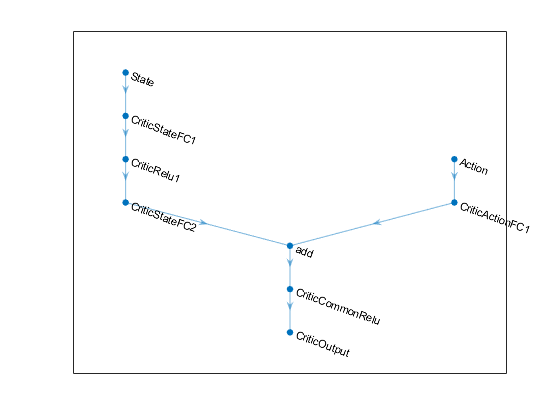

figure
plot(criticNetwork)

Specify options for the critic representation using [`rlRepresentationOptions`](docid:rl_ref#mw_45ccf57d-64f0-4822-8000-3f0f44f2572e).

criticOpts = rlRepresentationOptions('LearnRate',1e-03,'GradientThreshold',1,'UseDevice',"cpu"); % opcoes para o objeto critico, taxa de aprendizado e limite para o gradiente em 1 reduzindo o quando os parametros da rede podem mudar em cada interacao

Create the critic representation using the specified deep neural network and options. You must also specify the action and observation specifications for the critic, which you obtain from the environment interface. For more information, see [`rlQValueRepresentation`](docid:rl_ref#mw_6e9cf856-c679-4834-97e1-1349c4a21e43).

critic = rlQValueRepresentation(criticNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},criticOpts); %cria a representacao do Value do agente, o critico, os nomes tem que bater com os rede 

Given observations, a DDPG agent decides which action to take using an actor representation. To create the actor, first create a deep neural network with one (3!) input, the observation, and one output, the action.

Construct the actor in a similar manner to the critic. For more information, see [`rlDeterministicActorRepresentation`](docid:rl_ref#mw_425a8728-2966-45c4-9d2a-488aa4a506bf).

actorNetwork = [
    imageInputLayer([numObservations 1 1],'Normalization','none','Name','State')
    fullyConnectedLayer(3, 'Name','actorFC2')
    tanhLayer('Name','actorTanh')                                                   
    fullyConnectedLayer(numActions,'Name','Action')
    ];

actorOptions = rlRepresentationOptions('LearnRate',1e-04,'GradientThreshold',1,'UseDevice',"cpu");

actor = rlDeterministicActorRepresentation(actorNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},actorOptions);

To create the DDPG agent, first specify the DDPG agent options using [rlDDPGAgentOptions](docid:rl_ref#mw_5e9a4c5d-03d5-48d9-a85b-3c2d25fde43c).

agentOpts = rlDDPGAgentOptions(...
    'SampleTime',Ts,...
    'TargetSmoothFactor',1e-3,...           %taxa de aprendizado da value
    'DiscountFactor',1.0, ...
    'MiniBatchSize',64, ...                 % quantidade de passos que serão processados no treinamento, técnica que reduz o esforço computacional e da chance de fugir de minimos locais  % mini-batch gradiente descent
    'ExperienceBufferLength',1e6); 
agentOpts.NoiseOptions.Variance = 0.3;      % ruido para as acoes aumenta a chance dele fazer mais exploracao no inicio do treinamento 
agentOpts.NoiseOptions.VarianceDecayRate = 1e-5; % esse ruido vai decair com o tempo

Then, create the DDPG agent using the specified actor representation, critic representation, and agent options. For more information, see [rlDDPGAgent](docid:rl_ref#mw_7e49ed9c-eea8-4994-8532-c7f66d5359ef).

agent = rlDDPGAgent(actor,critic,agentOpts);

## Train Agent

To train the agent, first specify the training options. For this example, use the following options:

- Run each training for at most `5000` episodes. Specify that each episode lasts for at most `200` time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option) and disable the command line display (set the `Verbose` option to `false`).

- Stop training when the agent receives an average cumulative reward greater than 800 over 20 consecutive episodes. At this point, the agent can control the level of water in the tank.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

maxepisodes = 5000;
maxsteps = ceil(Tf/Ts);
trainOpts = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes, ...
    'MaxStepsPerEpisode',maxsteps, ...
    'ScoreAveragingWindowLength',20, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',800);

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training is a computationally intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = false;

if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load the pretrained agent for the example.
    load('WaterTankDDPG.mat','agent')
end

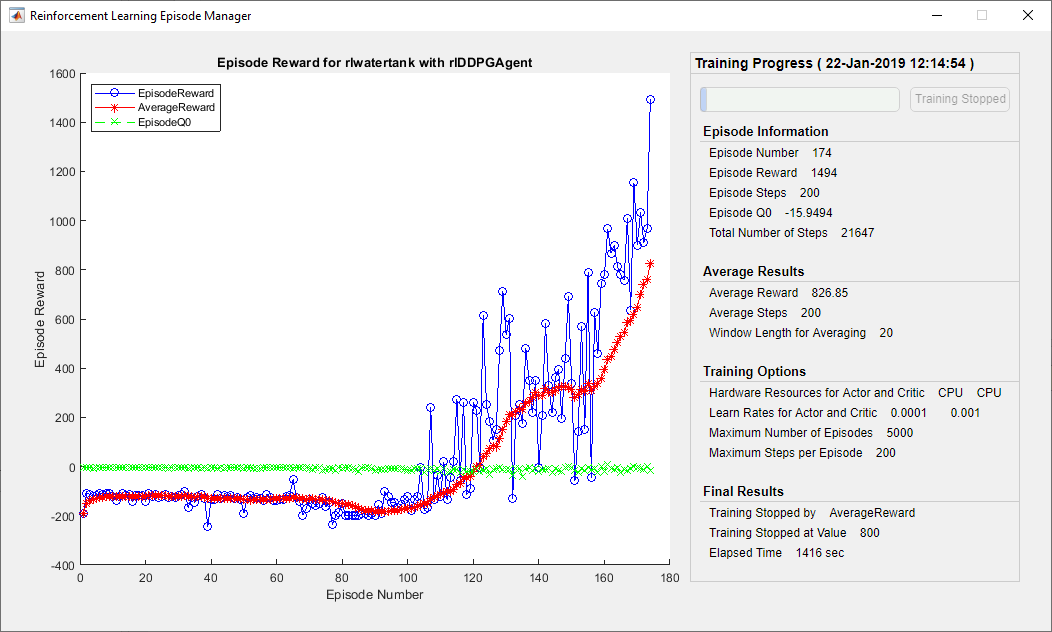

## Validate Trained Agent

Validate the learned agent against the model by simulation.

simOpts = rlSimulationOptions('MaxSteps',maxsteps,'StopOnError','on');
experiences = sim(env,agent,simOpts);

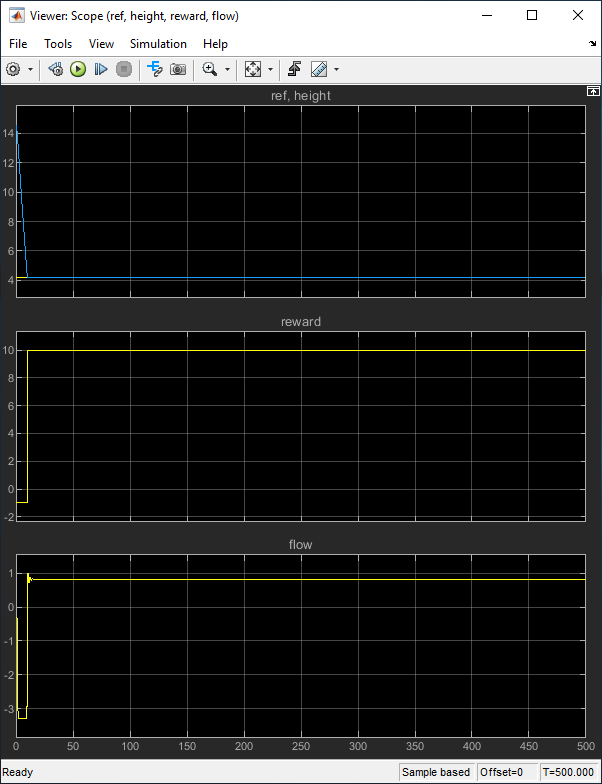

## Local Function

function in = localResetFcn(in)

% randomize reference signal
%h = 3*randn + 10;
%while h <= 0 || h >= 20
%    h = 3*randn + 10;
%end
blk = sprintf('meurlwatertank/Desired \nWater Level');
variancia=9;
me=10;
h = sqrt(variancia).*randn(1,1) + me;
in = setBlockParameter(in,blk,'Value',num2str(h));

% randomize initial height
%h = 3*randn + 10;
%while h <= 0 || h >= 20
%    h = 3*randn + 10;
%end
blk = 'meurlwatertank/Water-Tank System/H';
variancia=9;
me=10;
h = sqrt(variancia).*randn(1,1) + me;
in = setBlockParameter(in,blk,'InitialCondition',num2str(h));

end

*Copyright 2019 The MathWorks, Inc.*